# Generate ICDM color gamut ring chart

## Input data

rgb_ddl was copied from C:\Users\wayne\Documents\GitHub\gamut-volume-m\samples\lcd.txt

% all RGB values to be tested
load rgb_ddl.mat


## Predict spectral output using RiftSim.output

rs = RiftSim(1)

obj =   RiftSim with properties:

      dataspec: []
        ramp_r: []
        ramp_g: []
        ramp_b: []
         lut_x: []
           lut: []
            sc: 0.5000
        spec_r: []
        spec_g: []
        spec_b: []
     classpath: 'C:\Users\wayne\Documents\GitHub\MIS_acquire\@RiftSim'
    gamma_srgb: []
         vec_r: []
         vec_g: []
         vec_b: []
          HIMS: []
      vec_file: 'OL490_vec_HIMS1.mat'


rs =   RiftSim with properties:

      dataspec: [1024×401 double]
        ramp_r: [256×401 double]
        ramp_g: [256×401 double]
        ramp_b: [256×401 double]
         lut_x: [18×1 double]
           lut: [18×3 double]
            sc: 0.5000
        spec_r: [1.3350e-26 1.3120e-26 1.2895e-26 1.5235e-06 4.5915e-07 5.3700e-07 1.3730e-06 1.4820e-06 4.3015e-07 8.5450e-07 1.1380e-26 1.1230e-26 3.4960e-06 1.0790e-06 2.3215e-06 1.0495e-26 1.0310e-26 1.0090e-26 9.9000e-27 9.7350e-27 9.5450e-27 … ]
        spec_g: [2.3440e-06 8.7700e-06 2.6370e-06 5.2150e-07 2.7965e-06 4.1865e-06 2.2615e-06 6.4850e-06 1.1930e-06 1.9235e-26 1.8970e-26 1.8715e-26 1.8385e-26 1.8060e-26 5.0750e-07 3.8220e-07 2.5450e-07 4.4245e-06 2.8315e-06 4.2295e-06 1.6335e-05 … ]
        spec_b: [3.5625e-06 2.3105e-08 2.1495e-26 4.9065e-06 1.4790e-06 1.7295e-06 4.4215e-06 1.9895e-26 5.7400e-08 3.8595e-06 6.1550e-06 5.8000e-06 1.2140e-05 1.4555e-05 6.3150e-06 5

XYZ = zeros(602,3);
for i = 1:602
    rgb = rgb_ddl(i,:);
    s = rs.output(rgb);
    s41 = s(1:10:401)';
    XYZ(i,:) = ColorConversionClass.spd2XYZ(s41) * 20000;
end


## Construct the CGATS table

seq = [1:602]'

seq =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


cgat = [seq rgb_ddl XYZ];

## Manually edit the CGATS file

type CGATS_rift.txt

CGATS.17
FORMAT_VERSION	2
CREATED	2017-10-17 15:05:08 UTC+9
PRODUCT	MOBILE PHONE
DISPLAY_TYPE	RGBW LCD
INSTRUMENT	Konica-Minolta	CA-410		
SYNC_MODE	INT	60 Hz
MEASUREMENT_SPEED	FAST
AVERAGING_TIMES	5
AMBIENT_TEMPERATURE	24
KEYWORD	SampleID
NUMBER_OF_FIELDS	7
BEGIN_DATA_FORMAT
SampleID	RGB_R	RGB_G	RGB_B	XYZ_X	XYZ_Y	XYZ_Z
END_DATA_FORMAT
NUMBER_OF_SETS	602
BEGIN_DATA
1	0	0	0	0.0159021433470667	0.0158694613959333	0.00951903233833333
2	0	0	25	0.123750026930917	0.0488583501834833	0.630103983936083
3	0	0	51	0.479585273610766	0.154037630502383	2.63459211754723
4	0	0	76	1.11694311972632	0.357934307515434	6.21888809202708
5	0	0	102	2.09407812413332	0.638756794525433	11.7769449586371
6	0	0	127	3.29666250833982	0.990467288103734	18.6195565054321
7	0	0	153	4.99855145140882	1.50264695265543	28.1760971329871
8	0	0	178	6.93229865881082	2.08232885386643	39.1327230186871
9	0	0	204	9.14660140094382	2.72820776246043	51.7807640527471
10	0	0	229	12.5427870603638	3.76668674976543	70.7204168912971
11	0	0	255	

## Run `gamut-volume-m`

see `https://github.com/CIELab-gamut-tools/gamut-volume-m`

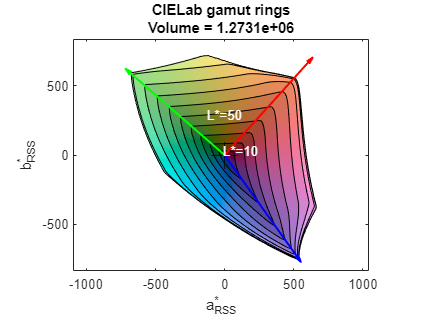

gamut = CIELabGamut();
PlotRings(gamut);
srgb = SyntheticGamut('srgb');
PlotRings(gamut,srgb,'RefLine','--y');

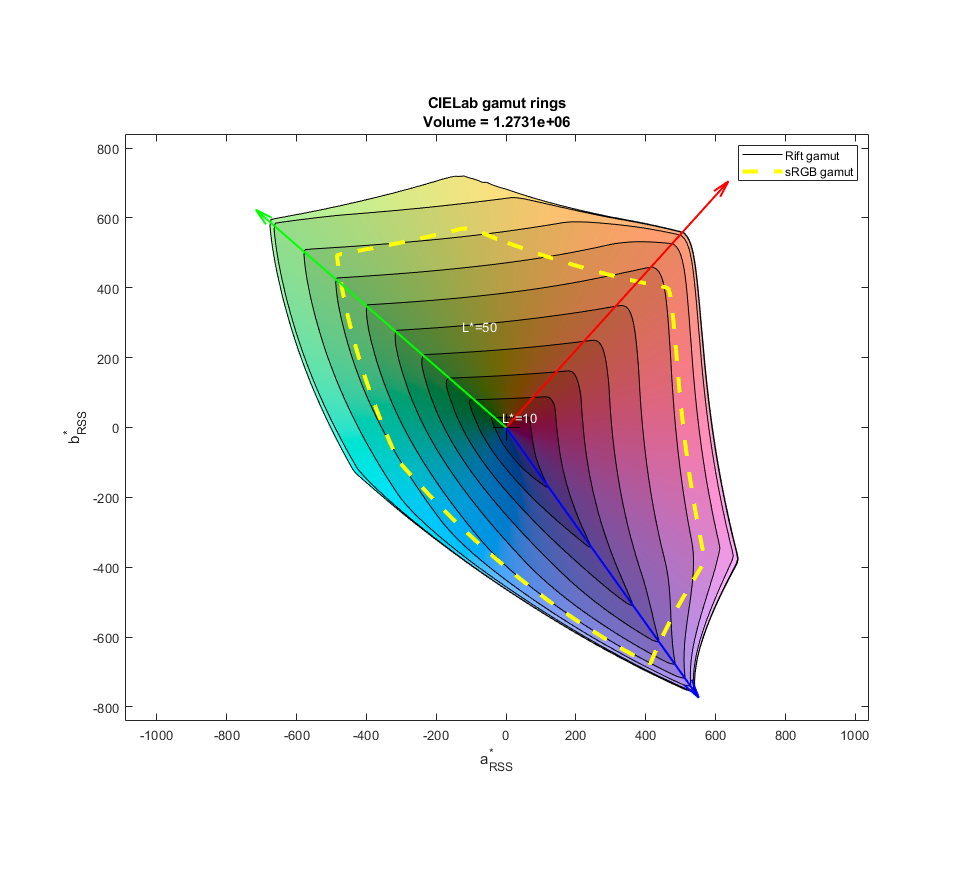

legend('Rift gamut','sRGB gamut');

hgif = gcf;
set(hgif,"Visible",'on')
hgif.Position = [591 188 960 886];
saveas(hgif,'Ring_rift.png')